
$$m_1\ddot{x}_1 + c_1\dot{x}_1 + k_1x_1-c_1\dot{x}_2-k_1x_2=f$$



$$m_2\ddot{x}_2 + (c_1+c_2)\dot{x}_2 + (k_1+k_2)x_2-c_1\dot{x}_1-k_1x_1 =0$$


% %defining f
% t=0:10:600;
% 
% f=sin(10*t);
m1  =  10;      % Mass 1[kg]
m2  =  100;     % Mass 2[kg] 
c1  =  100;     % Damping Coefficient 1[Ns/m]
c2  =  1000;    % Damping Coefficient 2[Ns/m]
k1  =  1e4;     % Spring Coefficient 1[N/m]
k2  =  1e5;     % Spring Coefficient 2[N/m]

T   =  10;      % Simulation stop time[s]

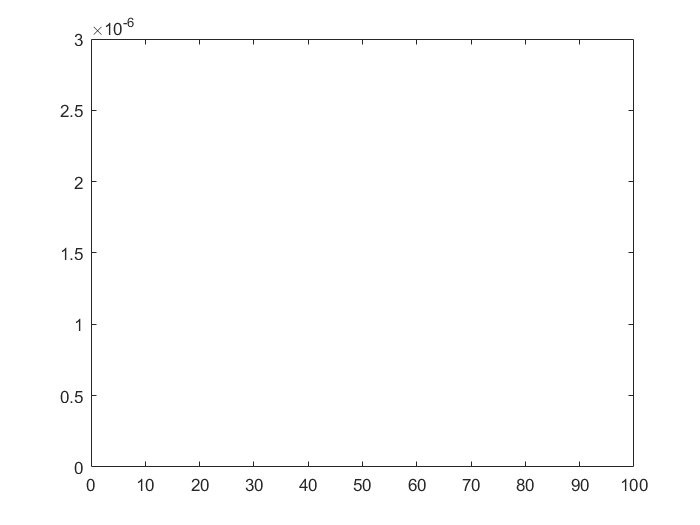

[tt,X]=ode45(@ode,[0 100],[0,0,0,0]);
plot(tt,X(1));
hold on;
plot(tt,X(3));
hold off;

% T = 0:0.001:10;
% S = [0.5 0];
% [t, y] = ode45(@odefun, T, S);
% plot(t,y)
% legend({'Position', 'Speed'});
% ylabel('Position / Speed [m / m/s]')
% xlabel('Time [s]')
% title('mass-spring-damper system');
% function dydt = odefun(~,x)
%      F = 1*x(1)^3 - 1*x(1)^2 + 1*x(1);
%     dydt = [x(2); 
%    - F - 0.1/50*x(2) - 2*x(1)];
% end
%plot(tt,X(1))

function dxdt = ode(t,x)
m1  =  10;      % Mass 1[kg]
m2  =  100;     % Mass 2[kg] 
c1  =  100;     % Damping Coefficient 1[Ns/m]
c2  =  1000;    % Damping Coefficient 2[Ns/m]
k1  =  1e4;     % Spring Coefficient 1[N/m]
k2  =  1e5;     % Spring Coefficient 2[N/m]
F   =  3*sin(10*t);
dxdt = [x(2);
        F + (1/m1)*(k1*x(3)  +  c1*x(4)  -  m1*x(1)  -  c1*x(2));
        x(4);
        (1/m2)*((-k1-k2)*x(3)  +  (-c1-c2)*x(4)  +  k1*x(1)  +  c1*x(2))];
end